### Baseline C57BL6/J

#### **Number of escape trials directed at the LED across conditions**

Data

% Correct Animal IDs as strings
AnimalID = [repmat("A01",3,1);
            repmat("A02",3,1);
            repmat("A03",3,1);
            repmat("A04",3,1);
            repmat("A05",3,1);
            repmat("A06",3,1);
            repmat("A07",3,1);
            repmat("A08",3,1);
            repmat("A09",3,1);
            repmat("A10",3,1);
            repmat("A11",3,1);
            repmat("81-10",3,1);
            repmat("81-20",3,1);
            repmat("81-21",3,1);
            repmat("81-30",3,1)];

AnimalID = categorical(AnimalID);  % ✅ Must be categorical

% Condition setup
ConditionNum = repmat([2; 4; 6], 15, 1);
Condition = categorical(ConditionNum, [2 4 6], {'2 holes', '4 holes', '6 holes'});

% LED-directed trials
LEDdirected = [1; 1; 1;
    2; 0; 1;
    3; 1; 0; 
    1; 0; 0;
    2; 1; 0;
    2; 1; 1;
    0; 0; 1;
    2; 1; 1;
    2; 2; 1;
    2; 1; 2;
    1; 0; 0;
    0; 0; 0;
    3; 2; 0;
    3; 0; 2;
    0; 0; 0;];

% Create table
data = table(AnimalID, Condition, LEDdirected);

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              45
    Fixed effects coefficients           3
    Random effects coefficients         15
    Covariance parameters                1
    Distribution                    Poisson
    Link                            Log   
    FitMethod                       MPL   

Formula:
    LEDdirected ~ 1 + Condition + (1 | AnimalID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    127.45    134.68    -59.725          119.45  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE         tStat     DF    pValue      Lower       Upper   
    {'(Intercept)'      }         0.46798    0.21048    2.2234    42    0.031624    0.043216     0.89275
    {'Condition_4 holes'}        -0.87547    0.37639    -2.326    42     0.02492      -1.635    -0.11589
    {'Co

A GLMM was fit to model the number of **LED-directed trials** using **Condition** as a fixed effect and **AnimalID** as a random intercept to account for repeated measures across animals.

- **Outcome variable**: `LEDdirected` (count)

- **Fixed effects**: `Condition` (levels: 2 holes [reference], 4 holes, 6 holes)

- **Random effects**: Varying intercepts for each animal (`AnimalID`)

- **Distribution**: Poisson (appropriate for count data)

- **Link function**: Log

- **Method**: Maximum Pseudo-Likelihood (MPL)

glmm = fitglme(data, ...
    'LEDdirected ~ Condition + (1|AnimalID)', ...
    'Distribution', 'Poisson', 'Link', 'log');
disp(glmm)

Error using internal.stats.parseArgs
Wrong number of arguments.

Error in multcompare (line 121)
        internal.stats.parseArgs(okargs,defaults,varargin{:});

Plot the data.

The plot will show the **predicted number of LED-directed trials by condition**, with **95% confidence intervals** around the group means.

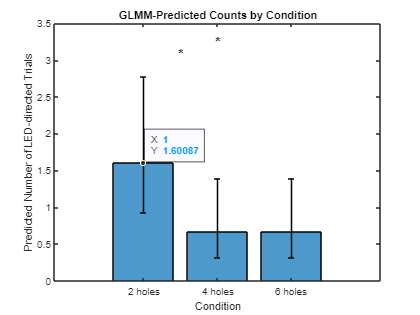

     Condition     MeanPredictedCount    CILower    CIUpper
    ___________    __________________    _______    _______

    {'2 holes'}          1.6009          0.92243    2.7783 
    {'4 holes'}         0.66703          0.31957    1.3923 
    {'6 holes'}         0.66703          0.31957    1.3923 



% Unique condition levels
conditions = categories(data.Condition);

% Initialize arrays
meanPred = zeros(numel(conditions), 1);
ciLow = zeros(numel(conditions), 1);
ciHigh = zeros(numel(conditions), 1);

% Loop over condition levels
for i = 1:numel(conditions)
    % Create a dummy dataset to predict at population level
    newdata = table;
    newdata.Condition = categorical(repmat(conditions(i), 10, 1), conditions);
    newdata.AnimalID = categorical(repmat(data.AnimalID(1), 10, 1));  % arbitrary AnimalID for marginal prediction

    % Predict
    [yhat, ci] = predict(glmm, newdata);

    % Store mean and CI
    meanPred(i) = mean(yhat);
    ciLow(i) = mean(ci(:,1));
    ciHigh(i) = mean(ci(:,2));
end

% Plot
figure;
bar(meanPred, 'FaceColor', [0.3 0.6 0.8]);
hold on
errorbar(1:numel(conditions), meanPred, ...
    meanPred - ciLow, ciHigh - meanPred, ...
    'k.', 'LineWidth', 1.5);

set(gca, 'XTick', 1:numel(conditions), 'XTickLabel', conditions);

xlabel('Condition');
ylabel('Predicted Number of LED-directed Trials');
title('GLMM-Predicted Counts by Condition')

#### **Number of escape trials directed at the LED across test sessions**

Data

% Correct Animal IDs as strings
AnimalID2 = [repmat("A01",4,1);
            repmat("A02",4,1);
            repmat("A03",4,1);
            repmat("A04",4,1);
            repmat("A05",4,1);
            repmat("A06",4,1);
            repmat("A07",4,1);
            repmat("A08",4,1);
            repmat("A09",4,1);
            repmat("A10",4,1);
            repmat("A11",4,1);
            repmat("81-10",4,1);
            repmat("81-20",4,1);
            repmat("81-21",4,1);
            repmat("81-30",4,1)];

AnimalID2 = categorical(AnimalID2);  % ✅ Must be categorical

% Session (numeric)
Session = [1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4;
                1; 2; 3; 4];

% Convert to categorical with labels
Sessioncat = categorical(Session, [1 2 3 4], {'Session 1', 'Session 2', 'Session 3', 'Session 4'});

% Number of LED-directed trials per animal per condition
LEDdirected2 = [1; 1; 1; 1;
    2; 1; 0; 0;
    3; 0; 0; 0; 
    0; 1; 0; 2; 
    1; 0; 0; 1; 
    1; 2; 0; 1; 
    0; 2; 0; 0; 
    1; 2; 1; 2; 
    1; 0; 1; 2; 
    0; 1; 2; 2; 
    0; 0; 1; 1; 
    0; 0; 0; 0; 
    2; 3; 0; 1; 
    1; 1; 0; 3;
    0; 0; 1; 0];

% Create table
data2 = table(AnimalID2, Sessioncat, LEDdirected2);

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              60
    Fixed effects coefficients           4
    Random effects coefficients         15
    Covariance parameters                1
    Distribution                    Poisson
    Link                            Log   
    FitMethod                       MPL   

Formula:
    LEDdirected2 ~ 1 + Sessioncat + (1 | AnimalID2)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    185.72    196.2    -87.862          175.72  

Fixed effects coefficients (95% CIs):
    Name                            Estimate    SE         tStat       DF    pValue     Lower       Upper  
    {'(Intercept)'         }         -0.1431    0.27735    -0.51596    56    0.60792     -0.6987     0.4125
    {'Sessioncat_Session 2'}        0.074108    0.38516     0.19241    56    0.84812    -0.69747    0.8456

A GLMM was fit to model the number of **LED-directed trials** using Session as a fixed effect and **AnimalID** as a random intercept to account for repeated measures across animals.

- **Outcome variable**: `LEDdirected` (count)

- **Fixed effects**: Sessions (levels: Session 1 [reference], Session 2, Session 3, Session 4)

- **Random effects**: Varying intercepts for each animal (`AnimalID`)

- **Distribution**: Poisson (appropriate for count data)

- **Link function**: Log

- **Method**: Maximum Pseudo-Likelihood (MPL)

glmm2 = fitglme(data2, ...
    'LEDdirected2 ~ Sessioncat + (1|AnimalID2)', ...
    'Distribution', 'Poisson', 'Link', 'log');
disp(glmm2)

Plot the data.

The plot will show the **predicted number of LED-directed trials by condition**, with **95% confidence intervals** around the group means.

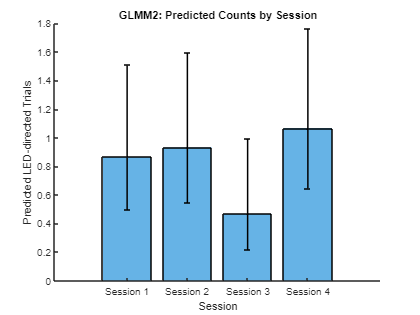

% Ensure proper variable types
data2.Sessioncat = categorical(data2.Sessioncat);
data2.AnimalID2 = categorical(data2.AnimalID2);

% Get the levels of the categorical predictor
sessions = categories(data2.Sessioncat);

% Initialize vectors for storing predictions and confidence intervals
meanPred = zeros(numel(sessions), 1);
ciLow = zeros(numel(sessions), 1);
ciHigh = zeros(numel(sessions), 1);

% Loop through each session level
for i = 1:numel(sessions)
    % Create dummy table for marginal prediction
    newdata = table;
    newdata.Sessioncat = categorical(repmat(sessions(i), 10, 1), sessions);
    newdata.AnimalID2 = repmat(data2.AnimalID2(1), 10, 1); % arbitrary ID; not used in marginal prediction

    % Predict the fitted response and 95% CI
    [yhat, ci] = predict(glmm2, newdata);

    % Store mean predictions and CI bounds
    meanPred(i) = mean(yhat);
    ciLow(i) = mean(ci(:,1));
    ciHigh(i) = mean(ci(:,2));
end

% Plot the predicted means with 95% CI error bars
figure;
bar(meanPred, 'FaceColor', [0.4 0.7 0.9]);
hold on;
errorbar(1:numel(sessions), meanPred, ...
    meanPred - ciLow, ciHigh - meanPred, ...
    'k.', 'LineWidth', 1.5);

% Customize axes and labels

set(gca, 'XTick', 1:numel(sessions), 'XTickLabel', sessions);
xlabel('Session');
ylabel('Predicted LED-directed Trials');
title('GLMM2: Predicted Counts by Session');
box off;

### 5xFAD

**Study Design Overview**

- **AnimalID: **Random effectUnique animal identifier

- **Timepoint:**Between-subjects`"2M"` vs `"3M"`

- **Group: **Between-subjects`"WT"` vs `"AD"`

- **Condition: **Within-subjects†`"2 Hole"`, `"4 Hole"`, `"6 Hole"`

- **LEDdirected: **Count outcomeNumber of LED-directed trials

#### **Number of escape trials directed at the LED across conditions**

Data

AnimalID3 = [repmat("62-167",3,1);
            repmat("63-170",3,1);
            repmat("71-304",2,1);
            repmat("72-307",3,1);
            repmat("73-310",2,1);
            repmat("73-311",2,1);
            repmat("74-313",2,1);
            repmat("96-830",2,1);

            repmat("62-168",3,1);
            repmat("63-169",3,1);
            repmat("71-305",2,1);
            repmat("72-308",2,1);
            repmat("73-309",3,1);
            repmat("74-312",2,1);
            repmat("95-828",3,1);
            repmat("96-829",3,1);
            repmat("96-831",3,1);
            
            repmat("64-215",1,1);
            repmat("64-216",2,1);
            repmat("64-217",3,1);
            repmat("99-830",3,1);
            repmat("110-142",3,1);
            repmat("110-143",3,1);
            repmat("112-147",3,1);
            repmat("112-148",3,1);

            repmat("65-218",3,1);
            repmat("65-219",3,1);
            repmat("99-828",3,1);
            repmat("99-829",3,1);
            repmat("99-830",3,1);
            repmat("110-141",3,1);
            repmat("111-144",3,1);
            repmat("111-145",3,1);
            repmat("112-146",3,1)];

Group3 = [repmat("AD",3,1);
            repmat("AD",3,1);
            repmat("AD",2,1);
            repmat("AD",3,1);
            repmat("AD",2,1);
            repmat("AD",2,1);
            repmat("AD",2,1);
            repmat("AD",2,1);

            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",2,1);
            repmat("WT",2,1);
            repmat("WT",3,1);
            repmat("WT",2,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            
            repmat("AD",1,1);
            repmat("AD",2,1);
            repmat("AD",3,1);
            repmat("AD",3,1);
            repmat("AD",3,1);
            repmat("AD",3,1);
            repmat("AD",3,1);
            repmat("AD",3,1);

            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1);
            repmat("WT",3,1)];

Timepoint3 = [repmat("3M",43, 1);
            repmat("2M", 48, 1)];

Condition3 = ["2 Hole"; "4 Hole"; "6 Hole"; 
    "2 Hole"; "4 Hole"; "6 Hole";
              "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole";           "6 Hole";
    "2 Hole"; "4 Hole";
    "2 Hole";           "6 Hole";
              "4 Hole"; "6 Hole";

    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; 
              "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; 
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";

              "4 Hole"; 
    "2 Hole"; "4 Hole"; 
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";

    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole";
    "2 Hole"; "4 Hole"; "6 Hole"];

LEDdirected3  = [2; 0; 0; 2; 1; 0; 2; 0; 3; 2; 1; 0; 1; 1; 1; 1; 2; 0; 0;
2; 0; 0; 0; 1; 1; 0; 2; 0; 1; 0; 0; 0; 2; 0; 1; 1; 2; 1; 0; 0; 1; 0; 1;
1; 2; 0; 1; 1; 1; 0; 1; 1; 1; 0; 0; 1; 0; 1; 3; 1; 1; 0; 0; 0;
1; 1; 1; 2; 1; 1; 3; 0; 1; 0; 1; 0; 0; 3; 1; 2; 0; 0; 0; 0; 2; 0; 0; 0; 1; 1; 0];

% Convert to table
data3 = table(AnimalID3, Timepoint3, Group3, Condition3, LEDdirected3);

% Convert categorical predictors
data3.AnimalID3 = categorical(data3.AnimalID3);
data3.Timepoint3 = categorical(data3.Timepoint3);
data3.Group3 = categorical(data3.Group3);
data3.Condition3 = categorical(data3.Condition3);

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              91
    Fixed effects coefficients          12
    Random effects coefficients         33
    Covariance parameters                1
    Distribution                    Poisson
    Link                            Log   
    FitMethod                       MPL   

Formula:
    LEDdirected3 ~ 1 + Timepoint3*Group3 + Timepoint3*Condition3 + Group3*Condition3 + Timepoint3:Group3:Condition3 + (1 | AnimalID3)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    290.16    322.8    -132.08          264.16  

Fixed effects coefficients (95% CIs):
    Name                                                 Estimate    SE         tStat       DF    pValue     Lower       Upper  
    {'(Intercept)'                              }         0.13353    0.35355     0.37768    79    0.70668     -

A GLMM was fit to model the number of **LED-directed trials**

This model includes:

- Main effects: Timepoint, Group, Condition

- All 2-way and 3-way interactions

- Random intercept for each animal to account for repeated measures

- Poisson distribution (appropriate for count data)

glmm3 = fitglme(data3, ...
    'LEDdirected3 ~ Timepoint3*Group3*Condition3 + (1|AnimalID3)', ...
    'Distribution', 'Poisson', 'Link', 'log');

disp(glmm3)

Plot the data.

The plot will show the **predicted number of LED-directed trials**

- A **subplot for each condition** (e.g., 2 Hole, 4 Hole, 6 Hole)

- Within each subplot: **bars grouped by timepoint**, colored by group (WT, AD, etc.)

- With **95% confidence intervals** on each bar

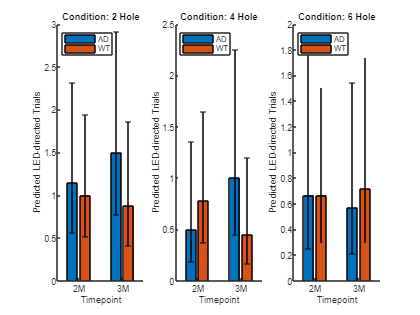

% Ensure variables are categorical
data3.Timepoint3 = categorical(data3.Timepoint3);
data3.Group3     = categorical(data3.Group3);
data3.Condition3 = categorical(data3.Condition3);
data3.AnimalID3  = categorical(data3.AnimalID3);

% Get all combinations of fixed effect levels
[tps, grps, conds] = ndgrid(categories(data3.Timepoint3), ...
                            categories(data3.Group3), ...
                            categories(data3.Condition3));

newdata = table;
newdata.Timepoint3 = categorical(tps(:), categories(data3.Timepoint3));
newdata.Group3     = categorical(grps(:), categories(data3.Group3));
newdata.Condition3 = categorical(conds(:), categories(data3.Condition3));

% Add dummy AnimalID for population-level prediction
newdata.AnimalID3 = repmat(data3.AnimalID3(1), height(newdata), 1);

% Predict outcomes
[pred, ci] = predict(glmm3, newdata);
newdata.Predicted = pred;
newdata.CI_Lower = ci(:,1);
newdata.CI_Upper = ci(:,2);

% --- Plotting: Group × Timepoint for each Condition ---
figure;
conds = categories(data3.Condition3);
colors = lines(numel(categories(data3.Group3)));

for i = 1:numel(conds)
    subplot(1, numel(conds), i);
    cond_i = conds{i};
    subdata = newdata(newdata.Condition3 == cond_i, :);
    
    % Prepare bar heights and errors
    [tpCats, ~, tpIdx] = unique(subdata.Timepoint3);
    [grpCats, ~, grpIdx] = unique(subdata.Group3);
    
    Y = zeros(numel(tpCats), numel(grpCats));
    YerrLow = Y;
    YerrHigh = Y;

    for r = 1:height(subdata)
        t = tpIdx(r);
        g = grpIdx(r);
        Y(t, g) = subdata.Predicted(r);
        YerrLow(t, g) = subdata.Predicted(r) - subdata.CI_Lower(r);
        YerrHigh(t, g) = subdata.CI_Upper(r) - subdata.Predicted(r);
    end

    % Plot bar chart
    b = bar(Y, 'grouped');
    hold on;

    % Add error bars
    for j = 1:numel(grpCats)
        x = b(j).XEndPoints;
        errorbar(x, Y(:,j), YerrLow(:,j), YerrHigh(:,j), ...

                 'k.', 'LineWidth', 1);
    end

    % Formatting
    xticklabels(tpCats);
    xlabel('Timepoint');
    ylabel('Predicted LED-directed Trials');
    title(['Condition: ' cond_i]);
    legend(grpCats, 'Location', 'northwest');
    box off;
end